# Análise dos dados dos experimentos e obtenção dos modelos

clear
size_image = [0, 0, 600, 400];

#### Constantes conhecidas

g = 9.81;      % gravidade
G_r = 4.4;     % relação da caixa de redução

#### Constantes medidas

V_max = 11.0;  % V  - multimetro na saída da ponte H
L_1 = 7.5/100; % m  - régua
L_2 = 13/100;  % m  - régua
m_1 = 40/1000; % kg - balança
m_2 = 27/1000; % kg - balança

#### Configurações do experimento

T = 40;
f0 = 0.1;
f1 = 10;

#### Configurações do Matlab 

type = 'P1';
init_sys = idproc(type);
opt = procestOptions;              
opt.InitialCondition = 'zero';     
opt.Display = 'off';     

## Experimento 1 - Pêndulo fixo em 180°

exp_1 = readtable("dados_exp1_a.txt");

exp_1.t = exp_1.t/1000;
exp_1.u = exp_1.u/1000;
exp_1.V = exp_1.u * V_max;
exp_1.theta_1 = exp_1.theta_1/1000;
exp_1

exp_1 = 11190×4 table
       t          u       theta_1       V   
    _______    _______    _______    _______

      4e-05      5e-05          0    0.00055
    0.01435    0.01803          0    0.19833
    0.02865    0.03596    0.06491    0.39556
    0.04295    0.05383    0.06491    0.59213
    0.05725     0.0716    0.06491     0.7876
    0.07156    0.08924    0.09736    0.98164
    0.08586    0.10669    0.12982     1.1736
    0.10016    0.12393    0.12982     1.3632
    0.11446    0.14093    0.16227     1.5502
    0.12876    0.15765    0.22718     1.7342
    0.14306    0.17405    0.29209     1.9146
    0.15736    0.19011    0.32454     2.0912
    0.17166    0.20577    0.38945     2.2635
    0.18596    0.22104    0.45436     2.4314
    0.20026    0.23586    0.51927     2.5945
    0.21456    0.25019    0.58418     2.7521


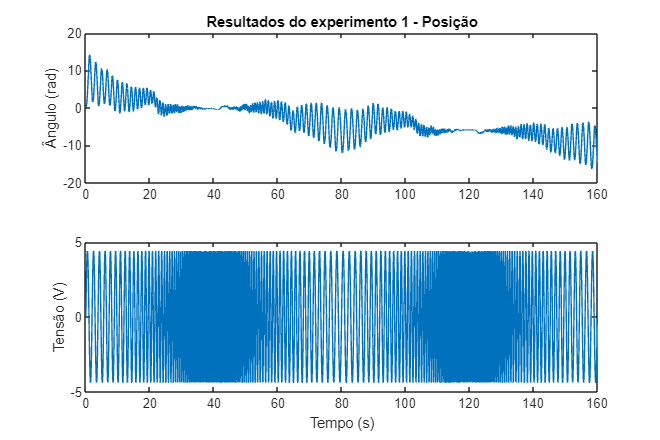

figure("Position", size_image)
subplot(2,1,1)
plot(exp_1.t, exp_1.theta_1)
xlim([0 T*4])
title("Resultados do experimento 1 - Posição"), ylabel("Ângulo (rad)")

subplot(2,1,2)
plot(exp_1.t, exp_1.V)
xlim([0 T*4]), xlabel("Tempo (s)"), ylabel("Tensão (V)")

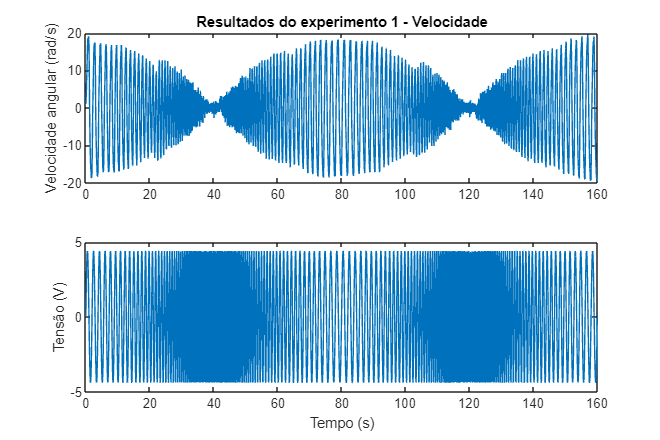

omega_1 = gradient(exp_1.theta_1, exp_1.t);
exp_1.omega_1 = smoothdata(omega_1, "movmean", 5);

figure("Position", size_image)
subplot(2,1,1)
plot(exp_1.t, exp_1.omega_1)
xlim([0 T*4])
title("Resultados do experimento 1 - Velocidade"), ylabel("Velocidade angular (rad/s)")

subplot(2,1,2)
plot(exp_1.t, exp_1.V)
xlim([0 T*4]), xlabel("Tempo (s)"), ylabel("Tensão (V)")
saveas(gcf, "result_exp1.png")

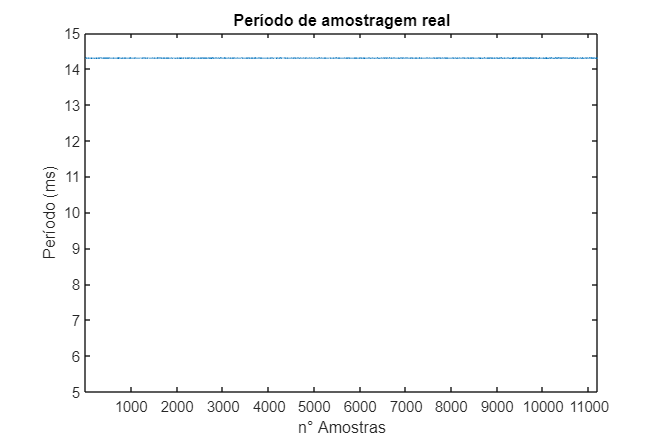

figure("Position", size_image)
plot(1e3*gradient(exp_1.t))
title("Período de amostragem real"), ylabel("Período (ms)"), xlabel("n° Amostras")
axis tight, ylim([5 15]);

Ts = mean(gradient(exp_1.t))

Ts = 0.0143

K1 = max(exp_1.omega_1)./max(exp_1.V) % ganho da planta

K1 = 4.4359

#### Estimativa do modelo a partir do ganho inicial K1

data_exp_1 = iddata(exp_1.omega_1, exp_1.V, Ts);
init_sys.Structure.Kp.Maximum = K1;

G_dtheta_1_exp1 = procest(data_exp_1, init_sys, opt);
G_dtheta_1_exp1 = tf(G_dtheta_1_exp1)

G_dtheta_1_exp1 =
 
  From input "u1" to output "y1":
     4.436
  ------------
  0.2609 s + 1
 
Continuous-time transfer function.
Model Properties


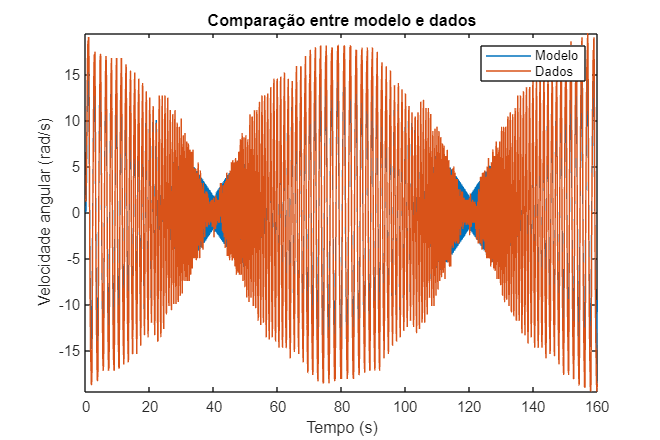

t_homogen = (0:length(exp_1.t)-1) * Ts;
y = lsim(G_dtheta_1_exp1, exp_1.V, t_homogen);

figure("Position", size_image)
plot(t_homogen, y, "LineWidth", 0.1)
hold on
plot(exp_1.t, exp_1.omega_1, "LineWidth", 0.1)
legend("Modelo", "Dados"), title("Comparação entre modelo e dados"), xlabel("Tempo (s)"), ylabel("Velocidade angular (rad/s)")
axis tight

## Experimento 2 - Motor sem haste do pêndulo

exp_2 = readtable("dados_exp2.txt");

exp_2.t = exp_2.t/1000;
exp_2.u = exp_2.u/1000;
exp_2.V = exp_2.u * V_max;
exp_2.theta_1 = exp_2.theta_1/1000;
exp_2

exp_2 = 23972×4 table
       t          u       theta_1       V   
    _______    _______    _______    _______

      4e-05      6e-05          0    0.00066
    0.01006    0.01263    0.03245    0.13893
    0.02007    0.02521    0.06491    0.27731
    0.03008    0.03776    0.09736    0.41536
     0.0401    0.05028    0.16227    0.55308
    0.05012    0.06275    0.22718    0.69025
    0.06013    0.07514    0.32454    0.82654
    0.07014    0.08748    0.45436    0.96228
    0.08015    0.09972    0.58418     1.0969
    0.09016    0.11187      0.714     1.2306
    0.10018    0.12392    0.87627     1.3631
     0.1102    0.13584      1.071     1.4942
    0.12021    0.14763     1.2657     1.6239
    0.13022    0.15927     1.4929      1.752
    0.14024    0.17076     1.7201     1.8784
    0.15025    0.18208     1.9797     2.0029


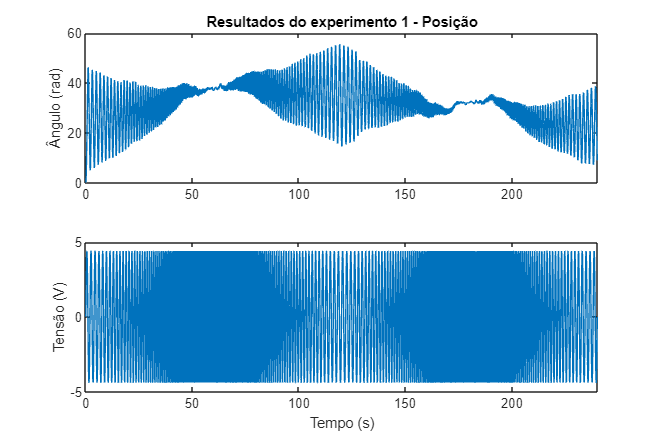

figure("Position", size_image)
subplot(2,1,1)
plot(exp_2.t, exp_2.theta_1)
xlim([0 T*4])
title("Resultados do experimento 1 - Posição"), ylabel("Ângulo (rad)")

subplot(2,1,2)
plot(exp_2.t, exp_2.V)
xlim([0 T*4]), xlabel("Tempo (s)"), ylabel("Tensão (V)")

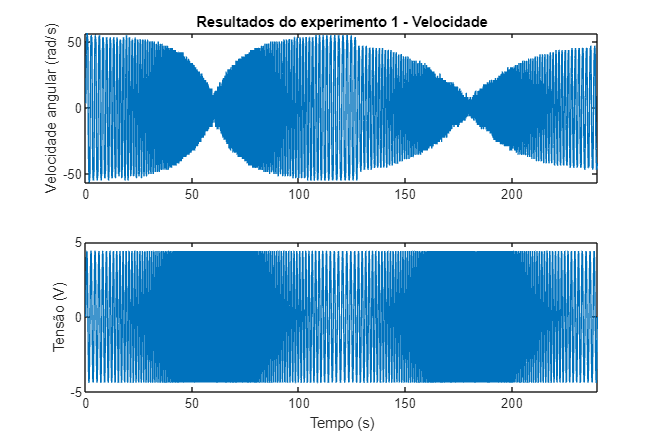

exp_2.omega_1 = gradient(exp_2.theta_1, exp_2.t);

figure("Position", size_image)
subplot(2,1,1)
plot(exp_2.t, exp_2.omega_1)
xlim([0 T*4])
title("Resultados do experimento 1 - Velocidade"), ylabel("Velocidade angular (rad/s)")

subplot(2,1,2)
plot(exp_2.t, exp_2.V)
xlim([0 T*4]), xlabel("Tempo (s)"), ylabel("Tensão (V)")

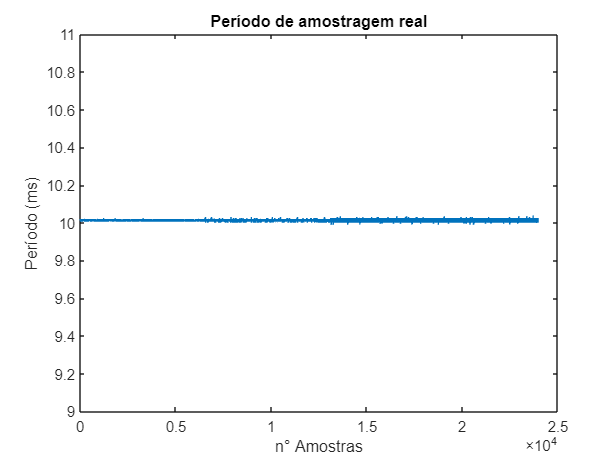

figure
plot(1e3*gradient(exp_2.t))
ylim([9 11]), title("Período de amostragem real"), ylabel("Período (ms)"), xlabel("n° Amostras")

Ts = mean(gradient(exp_2.t))

Ts = 0.0100

s = tf('s');
K2 = max(exp_2.omega_1)./max(exp_2.V) % ganho da planta

K2 = 12.8952

tau2 = 0.24; % constante de tempo da planta - parâmetro ajustado manualmente com base no gráfico abaixo
G_dtheta_1_exp2 = K2/(tau2*s + 1)

G_dtheta_1_exp2 =
 
     12.9
  ----------
  0.24 s + 1
 
Continuous-time transfer function.
Model Properties


t_homogen = (0:length(exp_2.t)-1) * Ts

t_homogen =          0    0.0100    0.0200    0.0300    0.0400    0.0501    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1302    0.1402    0.1502    0.1602    0.1702    0.1802    0.1902    0.2002    0.2103    0.2203    0.2303    0.2403    0.2503    0.2603    0.2703    0.2803    0.2904    0.3004    0.3104    0.3204    0.3304    0.3404    0.3504    0.3604    0.3705    0.3805    0.3905    0.4005    0.4105    0.4205    0.4305    0.4405    0.4506    0.4606    0.4706    0.4806    0.4906


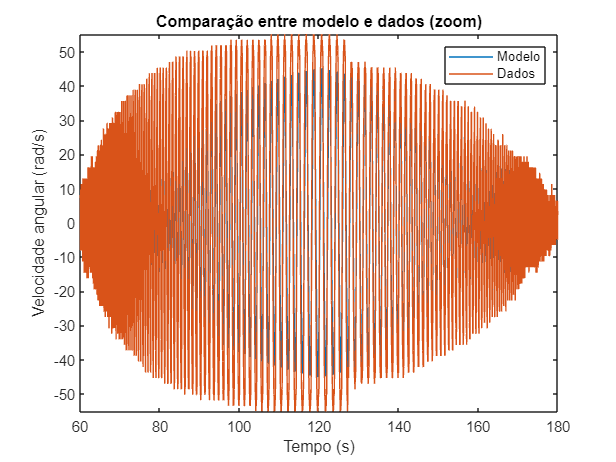

y = lsim(G_dtheta_1_exp2, exp_2.V, t_homogen);
figure
plot(t_homogen, y, "LineWidth", 0.1)
hold on
plot(exp_2.t, exp_2.omega_1, "LineWidth", 0.1)
legend("Modelo", "Dados"), title("Comparação entre modelo e dados (zoom)"), xlabel("Tempo (s)"), ylabel("Velocidade angular (rad/s)")
axis tight
xlim([T 3*T])

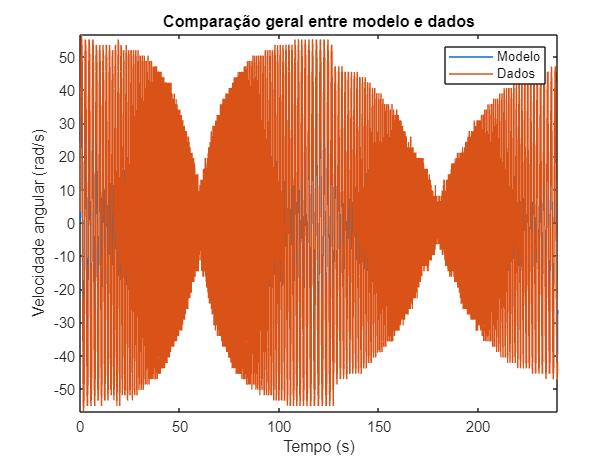

figure
plot(t_homogen, y, "LineWidth", 0.1)
hold on
plot(exp_2.t, exp_2.omega_1, "LineWidth", 0.1)
legend("Modelo", "Dados"), title("Comparação geral entre modelo e dados"), xlabel("Tempo (s)"), ylabel("Velocidade angular (rad/s)")
axis tight

## Heurística

% G_J1 = zpk(G_J1), G_J0 = zpk(G_J0)
% K_J1 = -G_J1.K/G_J1.P{1}, tau_J1 = -1/G_J1.P{1}
% G_J1n = tf(K_J1, [tau_J1 1])
% K_J0 = -G_J0.K/G_J0.P{1}, tau_J0 = -1/G_J0.P{1}
% G_J0n = tf(K_J1, [tau_J0 1])
% figure
% step(G_J1, [0 4])
% hold on
% step(G_J0, [0 4])
% legend("J_hat_1", "J_hat_0")
% figure
% step(G_J1n, [0 4])
% hold on
% step(G_J0n, [0 4])
% legend("J_hat_1", "J_hat_0")

### RPM máximo com K do G_J1

% format shortG
% K_J1*12/(2*pi)*60
% 1360*0.9
% format default

## Experimento motor fixo e pêndulo livre

### Transitorio

% inertia_3 = readtable("theta_0_J2_1.txt");
% 
% inertia_3.t = inertia_3.t/1000;
% inertia_3.theta_1 = inertia_3.theta_1/100;
% inertia_3.theta_2 = inertia_3.theta_2/100;
% inertia_3
% figure
% plot(inertia_3.t, inertia_3.theta_2)
% axis tight
% inertia_3(1:298,:) = [];
% inertia_3(inertia_3.t > 46,:) = [];
% 
% theta_2_dowm = mean(inertia_3.theta_2)
% inertia_3.theta_2 = inertia_3.theta_2 - theta_2_dowm;
% 
% figure
% plot(inertia_3.t, rad2deg(inertia_3.theta_2))
% axis tight
% Ts = mean(gradient(inertia_3.t))
% meanfreq(inertia_3.theta_2(inertia_3.t < 25), 1/Ts)
% F = ans
% omega_n = F*2*pi
% [pk, lk] = findpeaks(inertia_3.theta_2, "MinPeakHeight", 0.01);
% 
% figure
% plot(inertia_3.t, inertia_3.theta_2)
% hold on
% plot(inertia_3.t(lk), inertia_3.theta_2(lk), 'o')
% axis tight
% tlk = inertia_3.t(lk) - inertia_3.t(lk(1));
% pkn = pk/max(pk);
% 
% figure
% plot(tlk, pkn)
% idx = tlk < 25;
% pk_fit = polyfit(tlk(idx), log(pkn(idx)), 1);
% pk_est = polyval(pk_fit, tlk);
% 
% figure
% plot(tlk, log(pkn), tlk, pk_est)
% t = inertia_3.t - inertia_3.t(1);
% y = inertia_3.theta_2(1) * exp(pk_fit(1) * t) .* (cos(omega_n * t) - pk_fit(1)/(omega_n)*sin(omega_n * t));
% 
% figure
% plot(t, inertia_3.theta_2)
% hold on
% plot(t, y, '-')
% axis tight
% syms f J_hat_2 e 
% zeta = -pk_fit(1)/omega_n
% Eqn_J_hat_2 = [omega_n^2 == f/J_hat_2;
%                2*zeta*omega_n == e/J_hat_2]

### Regime permanente

% theta_2_eq = 164.1/100 - theta_2_dowm
% mass_eq = 12/1000; % kg
% tau_2 = mass_eq*g*L_2
% f = abs(tau_2/sin(theta_2_eq))

## Estração dos parâmetros

% G_J1p = zpk(G_J1n)
% G_J0p = zpk(G_J0n)
% syms J_hat_1 J_hat_2 k s_bar e

### Pêndulo

% l_2 = f/(g*m_2)
% Eqn_J_hat_2_f = subs(Eqn_J_hat_2)
% sol_J_hat_2 = solve(Eqn_J_hat_2_f, [J_hat_2, e])
% J_hat_2 = double(sol_J_hat_2.J_hat_2)
% b_2 = double(sol_J_hat_2.e)

### Motor

% d = G_r*s_bar/V_max;
% b = G_r^2*k;
% J_hat_0 = J_hat_1 + m_2*L_1^2;
% 
% b_J_hat_0 = -G_J0p.P{1}
% d_J_hat_0 = G_J0p.K
% b_J_hat_1 = -G_J1p.P{1}
% d_J_hat_1 = G_J1p.K
% Eqns = [d_J_hat_0 == d/J_hat_0;
%         b_J_hat_0 == b/J_hat_0;
%         d_J_hat_1 == d/J_hat_1;
%         b_J_hat_1 == b/J_hat_1]
% sol = solve(Eqns([1 2 3]), [J_hat_1 s_bar k])

### Valores Físicos Finais

% format shortE
% l_2, L_2
% J_hat_1 = double(sol.J_hat_1)
% J_hat_0 = double(subs(J_hat_0))
% s_bar = double(sol.s_bar)
% k = double(sol.k)
% format default

### Constantes de projeto

% format shortE
% J_hat_0, ...
% J_hat_2, ...
% b = G_r^2*k, ...
% c = L_1*l_2*m_2, ...
% d = G_r*s_bar/V_max, ...
% e = b_2, ...
% f = g*l_2*m_2
% format default
% save("params_furuta", "J_hat_0", "J_hat_2", "b", "c", "d", "e", "f")
